## DATA MINING AND NEURAL NETWORKS

## Prof. dr. ir. Johan A. K. Suykens

## Assignment 1 - Part 2 and 4

# Algorithms Comparison

# (exercise)

*Copyright of this version: HENRI DE PLAEN, KU LEUVEN*

*(based on previous works of the same course)*

*Date: 19 October 2020*

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%% DATA MINING AND NEURAL NETWORKS                                   %%%%
%%%% Prof. dr. ir. Johan A. K. Suykens                                 %%%%
%%%% Assignment 1 - Part 2 and 4                                       %%%%
%%%% Algorithms Comparison (exercise)                                  %%%%
%%%%                                                                   %%%%
%%%% Copyright of this version: HENRI DE PLAEN, KU LEUVEN              %%%%
%%%% (based on previous works of the same course)                      %%%%
%%%% Date: 19 October 2020                                            %%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%

Clears all variables stored in the workspace and closes all extra windows (e.g. plots or neural network training windows).

clear all ; close all ; clc ;

## ALGORITHMS

A script comparing performance of two algorithms.

- `traingd` `-` batch gradient descent (first order);

- `traingda` `-` gradient descent with adaptive learning rate (first order);

- `trainbfg - `BFGS quasi Newton (second order);

- `trainlm -` Levenberg - Marquardt (second order);

- `trainbr -` Bayesian regularization (L-M with regularization term)* [PART 4]*;

- *others*.

## Parameters

You can simply change the parameters of your experiment here. Feel free to adapt this whole document if you wish.

algorithm1 = 'trainbr' ;    % first algorithm to compare
algorithm2 = 'trainlm' ;    % second algorithm to compare

epochs_alg1 = 250 ; % number of epochs for the first algorithm
epochs_alg2 = 250 ; % number of ecochs for the second algorithm

n_neurons_l1 = 70;  % number of neurons in the first layer
n_neurons_l2 = 0;   % number of neurons in the second layer (put 0 in no second layer)

n_datapoints = 50 ;                       % number of datapoints
noise_level = 0.1; % standard deviation of the (optional) added noise

## Generation of examples and targets

x = linspace(0,3*pi, n_datapoints) ;      % input
y = sin(x.^2) ;                             % output (clean)
y = y + noise_level*randn(1, length(y)) ;   % addition of (optional) noise

p = con2seq(x) ;    % converts the input to a best format for the toolbox
t = con2seq(y) ;    % converts the output to a best format for the toolbox


## Creation of networks

Why is it relevant to put the same weights and biases for both networks?

%% CREATES THE NETWORKS
structure = [n_neurons_l1, n_neurons_l2] ;  % concatenates the number of neurons in one vector
structure(structure == 0) = [] ;            % prunes empty layers (the second one if it is 0 for example)
net1 = feedforwardnet(structure, algorithm1) ;     % creates a forst net with the first algorithm
net2 = feedforwardnet(structure, algorithm2) ;     % creates a second network with the second algorithm

%% INITIALIZE THEM WITH THE SAME WEIGHTS
net2.iw{1, 1} = net1.iw{1, 1} ;             % sets the same weights for both networks
net2.lw{2, 1} = net1.lw{2, 1} ;             % sets the same weights for both networks
net2.b{1} = net1.b{1} ;                     % sets the same biases for both networks
net2.b{2} = net1.b{2} ;                     % sets the same biases for both networks


## Training and simulation

Due to local minima, each training is different. If wou want general conclusions, you should work on a mean of many different examples. Why would it be relevant here, or not?

net1.trainParam.epochs = epochs_alg1 ;      % set the number of epochs for the training (network 1)
net2.trainParam.epochs = epochs_alg2 ;      % set the number of epochs for the training (network 2)

%% TRAIN NETWORK 1
tic ;                                       % start timer
net1 = train(net1,p,t) ;                    % train network 1
time_alg1 = toc ;                           % stop timer and save value
disp(['Training time for ' algorithm1 ': ' ...
    num2str(time_alg1) 's']) ;              % display timing results

Training time for trainbr: 0.8423s



%% TRAIN NETWORK 2
tic ;                                       % start timer
net2 = train(net2,p,t) ;                    % train network 2
time_alg2 = toc ;                           % stop timer and save value
disp(['Training time for ' algorithm2 ': ' ...
    num2str(time_alg2) 's']) ;              % display timing results

Training time for trainlm: 0.2001s



res1 = sim(net1,p) ;                     % simulate network 1 with the input vector p
res2 = sim(net2,p) ;                     % simulate network 2 with the input vector p


## Plots

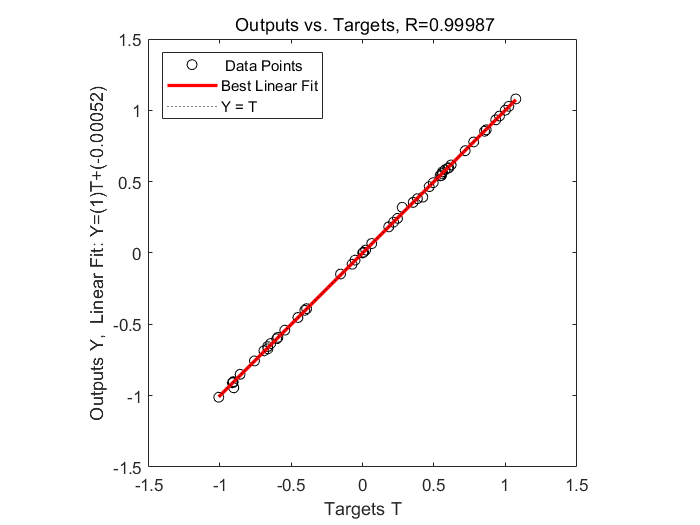

figure ;

subplot(2,2,[1,2]);                                         % a subplot functions as a grid, the two first arguments specify its size and the last one the position for the plot to come
plot(x,y,'bx',x,cell2mat(res1),'r',x,cell2mat(res2),'g');   % plot the sine function and the output of the networks
title('Results');
legend('target',algorithm1,algorithm2,'Location','north');

subplot(2,2,3);
postreg(cell2mat(res1),y);                                 % perform a linear regression analysis and plot the result (ideally all points should be on the identity line, meaning outputs and targets are equal)

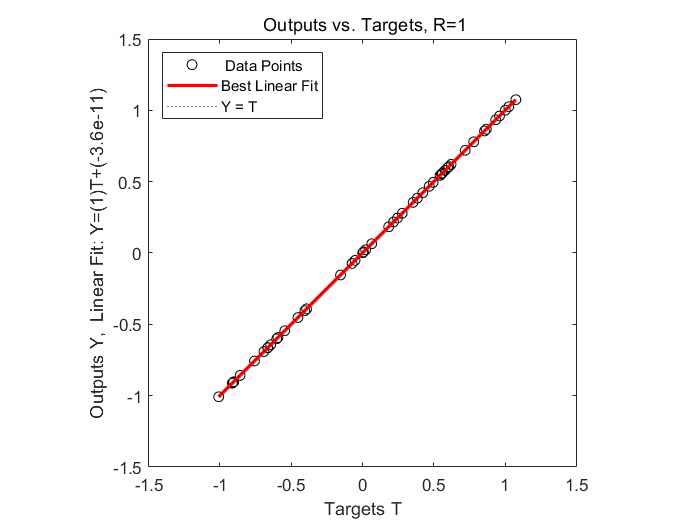


subplot(2,2,4);
postreg(cell2mat(res2),y);